Primeri za razdelek trikotnih Bézierjevih ploskev.

export_images = true; % nastavi na false da se slike ne exportajo

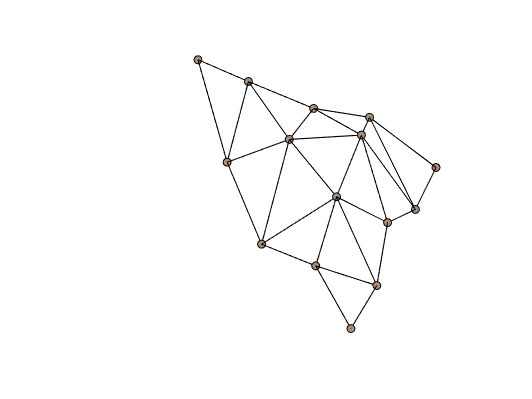

rng(5, 'twister')

Bx = [1 3 5 7 9; 3 5 7 9 NaN; 5 7 9 NaN NaN; 7 9 NaN NaN NaN; 9 NaN NaN NaN NaN];
By = [1 1 1 1 1; 3 3 3 3 NaN; 5 5 5 NaN NaN; 7 7 NaN NaN NaN; 9 NaN NaN NaN NaN];
Bz = [1 1.2 1.3 1.4 1.5; 1.2 1.3 1.5 1.6 NaN; 1.3 1.5 1.5 NaN NaN; 1.5 1.6 NaN NaN NaN; 1.8 NaN NaN NaN NaN];

n = size(Bx,1) - 1;

Bx = Bx + 0.5*rand(5);
By = By + 0.5*rand(5);
Bz = Bz + 0.2*rand(5);

BX = Bx';
BX = BX(:);
BX = BX(~isnan(BX));

BY = By';
BY = BY(:);
BY = BY(~isnan(BY));

BZ = Bz';
BZ = BZ(:);
BZ = BZ(~isnan(BZ));

figure
trimesh(trimeshgrid(n), BX, BY, BZ, 'EdgeColor', 'black', 'FaceColor', 'none');
hold on
scatter3(BX, BY, BZ, 'filled', 'MarkerFaceColor', '#AA8F78', 'MarkerEdgeColor', 'Black');
hold on

grid off
set(gca,'visible','off')

view([-70 20])

if export_images
    exportgraphics(gcf, 'b3_example1.pdf', 'ContentType', 'vector')
end

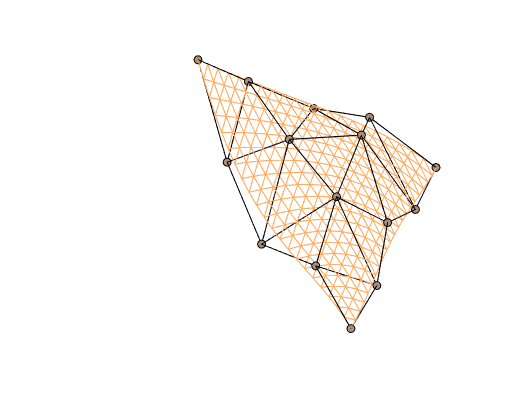

rng(5, 'twister')

Bx = [1 3 5 7 9; 3 5 7 9 NaN; 5 7 9 NaN NaN; 7 9 NaN NaN NaN; 9 NaN NaN NaN NaN];
By = [1 1 1 1 1; 3 3 3 3 NaN; 5 5 5 NaN NaN; 7 7 NaN NaN NaN; 9 NaN NaN NaN NaN];
Bz = [1 1.2 1.3 1.4 1.5; 1.2 1.3 1.5 1.6 NaN; 1.3 1.5 1.5 NaN NaN; 1.5 1.6 NaN NaN NaN; 1.8 NaN NaN NaN NaN];

n = size(Bx,1) - 1;

Bx = Bx + 0.5*rand(5);
By = By + 0.5*rand(5);
Bz = Bz + 0.2*rand(5);

BX = Bx';
BX = BX(:);
BX = BX(~isnan(BX));

BY = By';
BY = BY(:);
BY = BY(~isnan(BY));

BZ = Bz';
BZ = BZ(:);
BZ = BZ(~isnan(BZ));

[TRI, U] = trimeshgrid(21);

b = bezier3(Bx, By, Bz, U);

tri = triangulation(TRI, b);

figure
trisurf(tri, 'FaceColor', 'None', 'EdgeColor', '#FFAA5E');
hold on
trimesh(trimeshgrid(n), BX, BY, BZ, 'EdgeColor', 'black', 'FaceColor', 'none');
hold on
scatter3(BX, BY, BZ, 'filled', 'MarkerFaceColor', '#AA8F78', 'MarkerEdgeColor', 'Black');
hold on

grid off
set(gca,'visible','off')

view([-70 20])

if export_images
    exportgraphics(gcf, 'b3_example2.pdf', 'ContentType', 'vector')
end

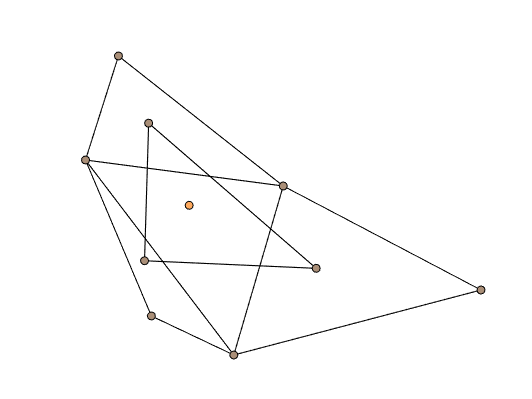

Bx = [1 1.5 3; 0.6 1.8 NaN; 0.8 NaN NaN];
By = [0.8 0.5 1; 2 1.8 NaN; 2.8 NaN NaN];

n = size(Bx,1) - 1;

BX = Bx';
BX = BX(:);
BX = BX(~isnan(BX));

BY = By';
BY = BY(:);
BY = BY(~isnan(BY));

figure
trimesh(trimeshgrid(n), BX, BY, zeros(size(BX)), 'EdgeColor', 'black', 'FaceColor', 'none');
hold on
scatter3(BX, BY, zeros(size(BX)), 'filled', 'MarkerFaceColor', '#AA8F78', 'MarkerEdgeColor', 'Black');
hold on

u = 1/3;
v = 1/4;
w = 1 - u - v;

for i = 1:n
    bx = NaN(n-i+1);
    by = NaN(n-i+1);

    for j = 1:(n-i+1)
        for k = 1:(n-i+1)
            bx(j, k) = u * Bx(j, k) + v * Bx(j, k+1) + w * Bx(j+1, k);
            by(j, k) = u * By(j, k) + v * By(j, k+1) + w * By(j+1, k);
        end
    end

    BX = bx';
    BX = BX(:);
    BX = BX(~isnan(BX));

    BY = by';
    BY = BY(:);
    BY = BY(~isnan(BY));

    if size(BX) == 1
        trimesh(trimeshgrid(n-i), BX, BY, zeros(size(BX)), 'EdgeColor', 'black', 'FaceColor', 'none');
        hold on
        scatter3(BX, BY, zeros(size(BX)), 'filled', 'MarkerFaceColor', '#FFAA5E', 'MarkerEdgeColor', 'Black');
        hold on
    else
        trimesh(trimeshgrid(n-i), BX, BY, zeros(size(BX)), 'EdgeColor', 'black', 'FaceColor', 'none');
        hold on
        scatter3(BX, BY, zeros(size(BX)), 'filled', 'MarkerFaceColor', '#AA8F78', 'MarkerEdgeColor', 'Black');
        hold on
    end

    Bx = bx;
    By = by;
end

grid off
set(gca, 'visible', 'off')

view([-0.50 90.00])

if export_images
    exportgraphics(gcf, 'b3_decasteljau.pdf', 'ContentType', 'vector')
end

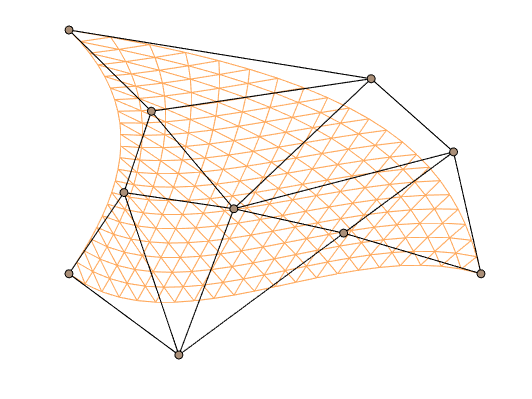

Bx = [0 0.8 2 3; 0.4 1.2 2.8 NaN; 0.6 2.2 NaN NaN; 0 NaN NaN NaN];
By = [0 -1 0.5 0; 1 0.8 1.5 NaN; 2 2.4 NaN NaN; 3 NaN NaN NaN];
Bz = zeros(size(Bx));

[bx, by, bz] = bezier3_elevate(Bx, By, Bz, 3);

n = size(Bx,1) - 1;
N = size(bx,1) - 1;

BX = Bx';
BX = BX(:);
BX = BX(~isnan(BX));

BY = By';
BY = BY(:);
BY = BY(~isnan(BY));

BX2 = bx';
BX2 = BX2(:);
BX2 = BX2(~isnan(BX2));

BY2 = by';
BY2 = BY2(:);
BY2 = BY2(~isnan(BY2));

[TRI, U] = trimeshgrid(21);

b = bezier3(Bx, By, Bz, U);
b2 = bezier3(bx, by, bz, U);

tri = triangulation(TRI, b);
tri2 = triangulation(TRI, b2);

figure
trisurf(tri, 'FaceColor', 'None', 'EdgeColor', '#FFAA5E');
hold on
trimesh(trimeshgrid(n), BX, BY, zeros(size(BX)), 'EdgeColor', 'black', 'FaceColor', 'none');
hold on
scatter3(BX, BY, zeros(size(BX)), 'filled', 'MarkerFaceColor', '#AA8F78', 'MarkerEdgeColor', 'Black');
hold on

grid off
set(gca, 'visible', 'off')

view([-0.50 90.00])

if export_images
    exportgraphics(gcf, 'b3_elevation1.pdf', 'ContentType', 'vector')
end

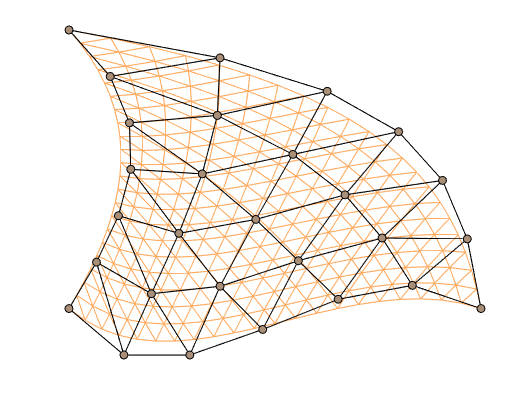


figure
trisurf(tri2, 'FaceColor', 'None', 'EdgeColor', '#FFAA5E');
hold on
trimesh(trimeshgrid(N), BX2, BY2, zeros(size(BX2)), 'EdgeColor', 'black', 'FaceColor', 'none');
hold on
scatter3(BX2, BY2, zeros(size(BX2)), 'filled', 'MarkerFaceColor', '#AA8F78', 'MarkerEdgeColor', 'Black');
hold on

grid off
set(gca, 'visible', 'off')

view([-0.50 90.00])

if export_images
    exportgraphics(gcf, 'b3_elevation2.pdf', 'ContentType', 'vector')
end

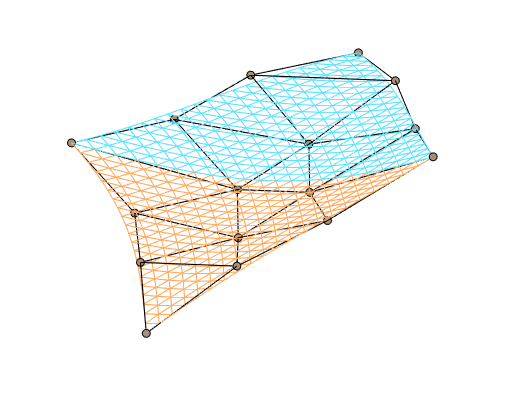

Bx = [0 0.2 0.4 0; 1 1.3 1.5 NaN; 2 2.1 NaN NaN; 3 NaN NaN NaN];
By = [0 1 2 3; 0.2 1.3 2.1 NaN; 0.4 1.5 NaN NaN; 0 NaN NaN NaN];
Bz = [0.3 0.6 0.8 1.1; 0.6 0.7 0.9 NaN; 0.8 0.9 NaN NaN; 1.1 NaN NaN NaN];

Bx2 = [0 1.5 2.1 3; -Bx(1,3)+Bx(2,3)+Bx(1,4) -Bx(2,2)+Bx(2,3)+Bx(3,2) -Bx(3,1)+Bx(4,1)+Bx(3,2) NaN; Bx(1,2)-2*Bx(1,3)+Bx(1,4)-2*Bx(2,2)+2*Bx(2,3)+Bx(3,2) Bx(2,1)-2*Bx(2,2)+Bx(2,3)-2*Bx(3,1)+2*Bx(3,2)+Bx(4,1) NaN NaN; 3 NaN NaN NaN];
By2 = [3 2.1 1.5 0; -By(1,3)+By(2,3)+By(1,4) -By(2,2)+By(2,3)+By(3,2) -By(3,1)+By(4,1)+By(3,2) NaN; By(1,2)-2*By(1,3)+By(1,4)-2*By(2,2)+2*By(2,3)+By(3,2) By(2,1)-2*By(2,2)+By(2,3)-2*By(3,1)+2*By(3,2)+By(4,1) NaN NaN; 3 NaN NaN NaN];
Bz2 = [1.1 0.9 0.9 1.1; -Bz(1,3)+Bz(2,3)+Bz(1,4) -Bz(2,2)+Bz(2,3)+Bz(3,2) -Bz(3,1)+Bz(4,1)+Bz(3,2) NaN; Bz(1,2)-2*Bz(1,3)+Bz(1,4)-2*Bz(2,2)+2*Bz(2,3)+Bz(3,2) Bz(2,1)-2*Bz(2,2)+Bz(2,3)-2*Bz(3,1)+2*Bz(3,2)+Bz(4,1) NaN NaN; 1.5 NaN NaN NaN];

n = size(Bx, 1) - 1;

BX = Bx';
BX = BX(:);
BX = BX(~isnan(BX));

BY = By';
BY = BY(:);
BY = BY(~isnan(BY));

BZ = Bz';
BZ = BZ(:);
BZ = BZ(~isnan(BZ));

BX2 = Bx2';
BX2 = BX2(:);
BX2 = BX2(~isnan(BX2));

BY2 = By2';
BY2 = BY2(:);
BY2 = BY2(~isnan(BY2));

BZ2 = Bz2';
BZ2 = BZ2(:);
BZ2 = BZ2(~isnan(BZ2));

[TRI, U] = trimeshgrid(21);

b = bezier3(Bx, By, Bz, U);
b2 = bezier3(Bx2, By2, Bz2, U);

tri = triangulation(TRI, b);
tri2 = triangulation(TRI, b2);

figure
trisurf(tri, 'FaceColor', 'None', 'EdgeColor', '#FFAA5E');
hold on
trisurf(tri2, 'FaceColor', 'None', 'EdgeColor', '#5EE3FF');
hold on
trimesh(trimeshgrid(n), BX, BY, BZ, 'EdgeColor', 'black', 'FaceColor', 'none');
hold on
scatter3(BX, BY, BZ, 'filled', 'MarkerFaceColor', '#AA8F78', 'MarkerEdgeColor', 'Black');
hold on
trimesh(trimeshgrid(n), BX2, BY2, BZ2, 'EdgeColor', 'black', 'FaceColor', 'none');
hold on
scatter3(BX2, BY2, BZ2, 'filled', 'MarkerFaceColor', '#AA8F78', 'MarkerEdgeColor', 'Black');

grid off
set(gca, 'visible', 'off')

view([-13.00 3.50])

if export_images
    exportgraphics(gcf, 'b3_spline.pdf', 'ContentType', 'vector')
end